%% Cantilever dynamic analysis 


$$I_0 \theta^¨ =-\mathrm{mg}\frac{l}{2}\mathrm{sin}\theta -\mathrm{Ksin}\theta L+\mathrm{Csin}\theta^{\ldotp }$$


% Cantilever data
clc; clear all;

l = 5.0;
h=0.2;
b=0.1;
A=h*b;
rhoo=7800;
m=A*l*rhoo;
w=A*rhoo;
K=22e6;
C=3e5;
E=210e9;
I=b*h^3/12;
theta0 = deg2rad(90);
g = 9.81;
Io = m*l^2/3;
tf = 2.0;

real_d=w*l^4/(8*E*I)*1000 % mm

real_d = 0.8705

Solution using 1 dof differential equations

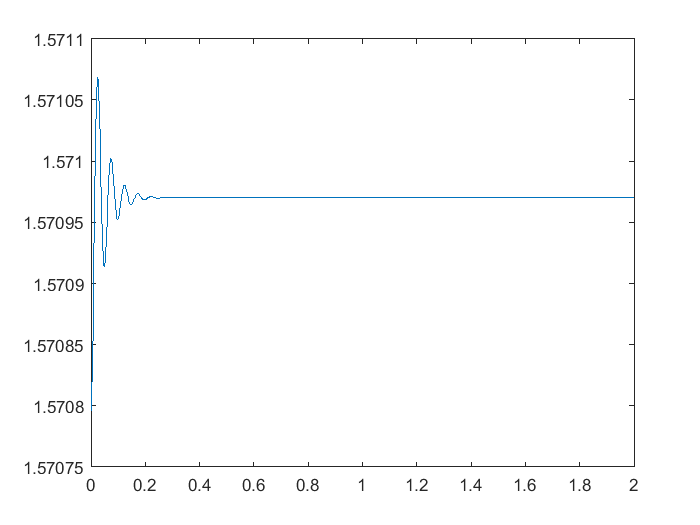

y0 = [theta0; 0.0]; % angle and its initial velocity

odefun = @(t, y) [-y(2); (m * -g * l / 2 * sin(y(1)) + K*sin(y(1)-theta0)*l - C*sin(y(2))) / Io ];
tspan = [0.0, tf];
[t, y] = ode45(odefun, tspan, y0);

plot(t, y(:, 1))


def=(y(1,1)-y(end,1))*l*1000 %mm

def = -0.8695

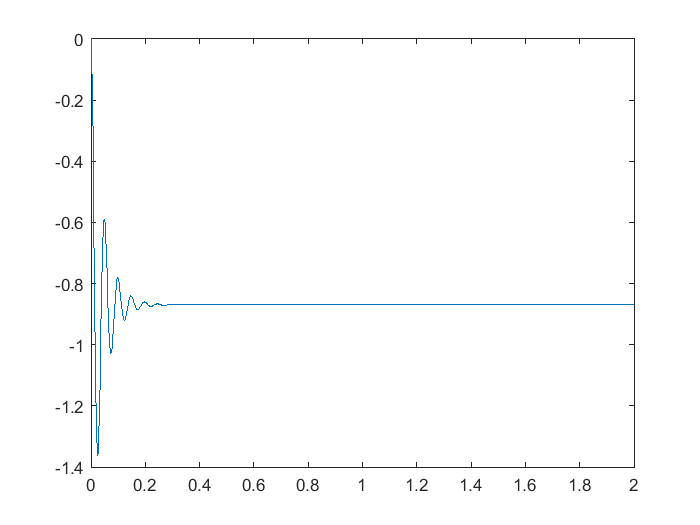


plot(t, (theta0-y(:, 1))*l*1000)